
% figure gamma v.s. angle %

clear all;
close all;

load('E:\Comagnetometer_Pub\gamma_simulation\gamma.mat')



% angle_list = [-4e-4:4e-5:4e-4];
% B_list=[0.1 1 2 3 3.85 3.9 3.95  4  4.05 4.1 4.2 5 6 7 7.9];
% 
% for k1 = 1:length(B_list)    
%     for k2 = 1:length(angle_list)
%         [f_mean(k1,k2),f_std(k1,k2)] = BscanXZ(angle_list(k2),B_list(k1)); 
%     end
% end
% 
% omega = f_mean.*2*pi;


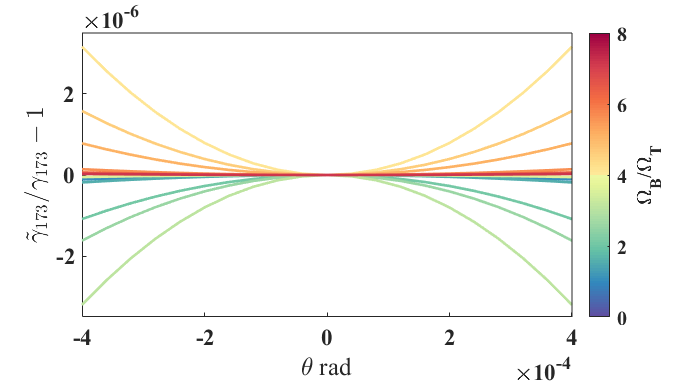


f1 = figure;
hold on;
cMap = getPyPlot_cMap('Spectral',128,0,"C:\Users\USTC\AppData\Local\Programs\Python\Python313\python");

delete = 18;
cMap(64-delete/2+1:64+delete/2,:) = [];
temp = cMap';
temp = fliplr(temp);
cMap1 = temp';
colormap(cMap1);
step = floor(length(cMap1)/length(B_list));

for k = 1:length(B_list)
    if mod(k,3) == 1
    l(k)=plot(angle_list,omega(k,:)/B_list(k)/(2*pi*5)-1,'-','MarkerSize',13,'LineWidth',2);
    elseif mod(k,3) == 2
        l(k)=plot(angle_list,omega(k,:)/B_list(k)/(2*pi*5)-1,'-','MarkerSize',13,'LineWidth',2);
    elseif mod(k,3) == 0
        l(k)=plot(angle_list,omega(k,:)/B_list(k)/(2*pi*5)-1,'-','MarkerSize',13,'LineWidth',2);
    end
    l(k).Color = cMap1(1+(k-1)*step,:);
    ld(k) = {['R_{\Omega} = ',num2str(B_list(k))]};
    %hold(ld(k),"on");
end

cbar = colorbar('Ticks',[0 0.25 0.5 0.75 1],...
         'TickLabels',{'0','2','4','6','8'});
cbar.Label.String = '\Omega_B/\Omega_T';
%cbar.FontName = 'Times New Roman';

x_low = min(angle_list);
x_high = max(angle_list);
y_low = -3.5e-6;
y_high = 3.5e-6;

xlim([x_low x_high]);
ylim([y_low y_high]);
yticks([-2 0 2]*1e-6);

set(gca,'FontName','Times New Roman','FontSize',17,'FontWeight','bold');

xlabel('\theta rad','FontName','Times New Roman','FontWeight','normal');
ylabel('$\tilde\gamma_{173}/\gamma_{173}-1$',...
    'Interpreter','latex');

grid off;
box off;

plot([x_low x_high],[y_high y_high],'Color',[0.15 0.15 0.15]);
plot([x_high x_high],[y_low y_high],'Color',[0.15 0.15 0.15]);

% legend([ld,'',''],...
%     'FontName','Arial','FontSize',16,'FontWeight','bold',...
%     'Location','northeast');

set(f1,'Visible','on','Position',[137,466,697,385]);


savefig(f1,'E:\Comagnetometer_Pub\gamma_simulation\gamma.fig');
saveas(f1,'E:\Comagnetometer_Pub\gamma_simulation\gamma.png');
saveas(f1,'E:\Comagnetometer_Pub\gamma_simulation\gamma.eps','psc');
saveas(f1,'E:\Comagnetometer_Pub\gamma_simulation\gamma.svg');


%save('E:\Comagnetometer_Pub\gamma_simulation\gamma.mat');


function [f_mean,f_std]=BscanXZ(angle,Bz)

%clear all;
%close all;
colors = npg(100);
F=5/2;
sigmax = spinOp(F,'x');
sigmay = spinOp(F,'y');
sigmaz = spinOp(F,'z');


%% 输入变量
start_point = 800;   % 不分析前几个周期
N = 1200;   % 共计N个周期
dN = 0.15;   % 计算步长为dN个周期

initial_angle = 0;   % 初始偏离理想极化

%angle = 3/400;   % 横向磁场角度
tensor = 1;   % tensor shift大小
%Bz = 50;   % Frequency量纲

phase0 = 0.5*pi;  % 第一次过零点前经历的相位


ham0 = 1*sigmax+1*sigmax^2;
ham1 = 2*pi*( (angle*sigmay+sigmaz)*Bz/sqrt(1+angle^2) + tensor*sigmaz^2);   % omega量纲

freq_center = Bz*F/0.5;   % Frequency量纲

initial_0 = zeros(2*F+1,1);
initial_0(1) = 1;
initial_0 = ham_evolve(sigmax+sigmax^2,initial_0,initial_angle);
initial = ham_evolve(ham1,initial_0,0.75*78/108/freq_center);
initial = ham_evolve(ham0,initial,pi/2);
%initial = ham_evolve(ham0,initial,pi/2);


timestep = dN*1/freq_center;
timeend = N*1/freq_center;
timelist = [0:timestep:timeend];


for k = 1:length(timelist)
    precess_state = ham_evolve(ham1,initial,timelist(k));
    final_state(:,k) = ham_evolve(ham0,precess_state,pi/2);
end
pop_state = abs(final_state).^2;

sz(:) = (pop_state(1,:)-pop_state(2*F+1,:))./(pop_state(1,:)+pop_state(2*F+1,:));




[contrast,cycle_n,zero_list,zero_mark] = cycle_count_function(sz,timelist,phase0);

for k = 1:length(zero_list)
    zero_state1 = ham_evolve(ham1,initial,zero_list(k));
    zero_state(:,k) = ham_evolve(ham0,zero_state1,pi/2);
end

pop_state1 = abs(zero_state).^2;
zero_sz(:) = (pop_state1(1,:)-pop_state1(2*F+1,:))./(pop_state1(1,:)+pop_state1(2*F+1,:));
zero_residual_phase = zero_sz/contrast.*zero_mark;

zero_phase = phase0+2*pi*[0:0.5:cycle_n]+zero_residual_phase;
freq_list = zero_phase./zero_list/(2*pi);
cycle_list = [phase0/(2*pi):0.5:phase0/(2*pi)+cycle_n];

freq_list(1:start_point*2) = [];
cycle_list(1:start_point*2) = [];

f_mean = mean(freq_list);
f_std = std(freq_list);



end
function final = ham_evolve(ham,initial,time)
try
    final = expm(-1i*ham.*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end
